clc;
clear all;
close all;
timespan = 60*1000; %ms
timeinterval = 10; %ms
nrofslots = timespan/timeinterval;

freqspan = 125e3;  %hz : 125khz -> 868.7 - 869.2 MHZ
freqinterval = 100; %hz
nrofchannels = 6;

ft = zeros(nrofslots, nrofchannels);

nrofdevices = 500;
nrofpackets = 1;
packetduration = 2000;


%LORA
% SF bitrate(bps) duration (for 25 bytes)
lora_duration = [12  293 682; 
        11  547 365;
        10  976 204;
        09 1757 113;
        08 3125  64;
        07 5478  36;
        06 9375 21];


packetduration = lora_duration(1,3);

colission = zeros(nrofdevices, nrofpackets);

sf = randi([1 nrofchannels], [nrofdevices nrofpackets]);
time = randi([1 floor(nrofslots - (packetduration*nrofpackets)/timeinterval)], [nrofdevices 1]);
for i = 1:nrofdevices
    time_offset = time(i, 1);
    
    for p = 1:nrofpackets    
        for k = -1:1:1
            if (sf(i, p)+k<1) | (sf(i, p)+k>nrofchannels)
                continue
            end
            duration = lora_duration(sf(i, p),3);
            for j = 1:ceil(duration/timeinterval)
               %freq(i, 1)
               if j+time_offset > nrofslots
                   continue
               end
               if  ft(j+time_offset, sf(i, p)+k) == 0
                   ft(j+time_offset, sf(i, p)+k) = 1;
               else
                    ft(j+time_offset, sf(i, p)+k) = 2;
                    colission(i, p) = 1;
               end
            end        
        end
        time_offset = time_offset + duration/timeinterval;
    end    
end

%colission
fail = sum(colission, 2) == nrofpackets;
sum(fail)

ans = 271

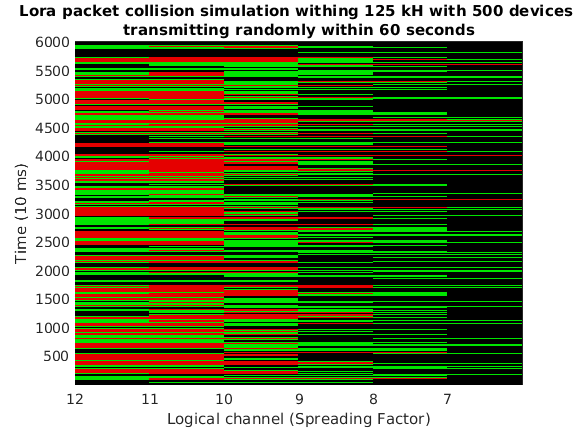


ft(1,1) = 1;
ft(1,2) = 2;
ft = [ft ones(6000,1)];
figure1 = figure();
pcolor(ft);

map2 = [0 0 0;  0 1 0 ;0 0.9 0; 0.9 0 0;];
colormap(map2);
shading flat;

titlestring = sprintf('Lora packet collision simulation withing 125 kH with %d devices \ntransmitting randomly within 60 seconds', ...
        nrofdevices);

title(titlestring);
xlabel('Logical channel (Spreading Factor)') % x-axis label
ylabel('Time (10 ms)') % y-axis label
ax = gca;
set(gca,'XTickLabel',{'12','11','10','9','8','7',''});


saveas(figure1, sprintf('lora_spectrum_%d_dev.fig',nrofdevices));
saveas(figure1, sprintf('lora_spectrum_%d_dev.png',nrofdevices));